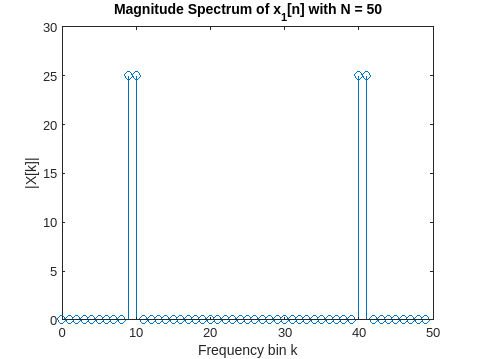

% Parameters
fs = 750;
N = 50;
n = 0:N-1;
f1 = 135;
f2 = 150;
Ts = 1/fs;

% Signal generation
x1 = cos(2*pi*f1*n*Ts) + cos(2*pi*f2*n*Ts);

% Compute DFT
X = fft(x1);

% Plot magnitude spectrum
k = 0:N-1;
stem(k, abs(X));
xlabel('Frequency bin k');
ylabel('|X[k]|');
title('Magnitude Spectrum of x_1[n] with N = 50');

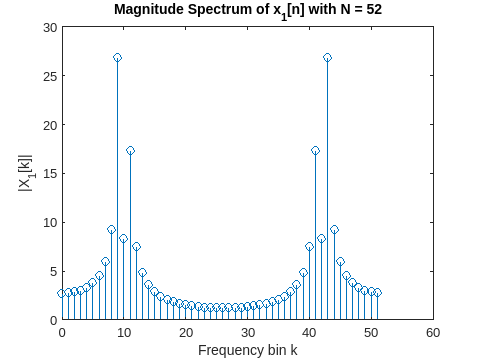

% New number of samples
N1 = N + 2;
n1 = 0:N1-1;

% Signal generation
x1_new = cos(2*pi*f1*n1*Ts) + cos(2*pi*f2*n1*Ts);

% Compute DFT
X1 = fft(x1_new);

% Plot magnitude spectrum
k1 = 0:N1-1;
stem(k1, abs(X1));
xlabel('Frequency bin k');
ylabel('|X_1[k]|');
title('Magnitude Spectrum of x_1[n] with N = 52');

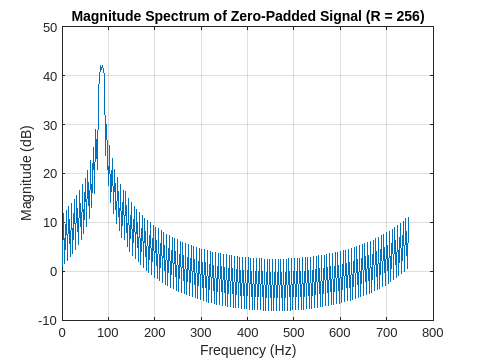


load('signal.mat');

x = x(:);

N = length(x);

R = 256;

x_padded = [x; zeros(R - N, 1)];

X = fft(x_padded);

Mag_X_dB = 20 * log10(abs(X));

fs = 750;
f = (0:R-1)*(fs/R);

% Plot the magnitude spectrum
figure;
plot(f, Mag_X_dB);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Zero-Padded Signal (R = 256)');
grid on;

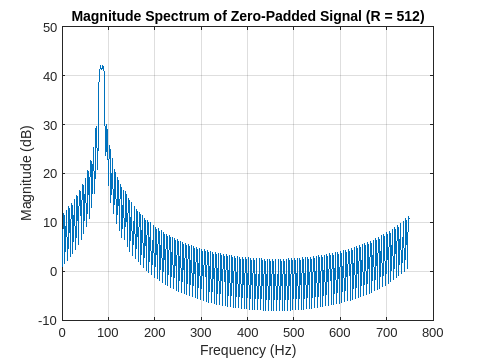

% Zero-padding to length R = 512
R = 512;
x_padded = [x; zeros(R - N, 1)];

% Compute DFT
X = fft(x_padded);

% Compute magnitude spectrum in dB
Mag_X_dB = 20*log10(abs(X));

% Frequency vector for plotting
f = (0:R-1)*(fs/R);

% Plot magnitude spectrum
plot(f, Mag_X_dB);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum of Zero-Padded Signal (R = 512)');
grid on;

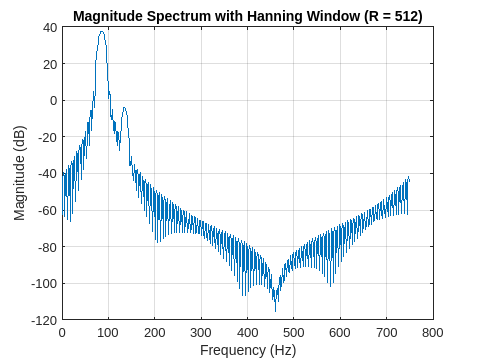

% Apply Hanning window
w_hann = hann(N);
x_hann = x .* w_hann;

% Zero-padding to R = 512
x_hann_padded = [x_hann; zeros(R - N, 1)];

% Compute DFT
X_hann = fft(x_hann_padded);

% Compute magnitude spectrum in dB
Mag_X_hann_dB = 20*log10(abs(X_hann));

% Plot magnitude spectrum
plot(f, Mag_X_hann_dB);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Spectrum with Hanning Window (R = 512)');
grid on;

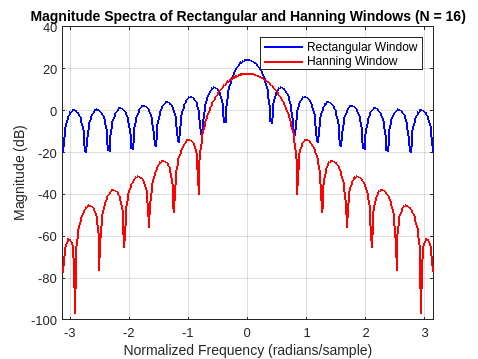

% Window length
Nw = 16;
R = 512;
w_rect = ones(Nw, 1);

% Generate the Hanning window
w_hann = hann(Nw);

% Zero-pad the windows to length R
w_rect_padded = [w_rect; zeros(R - Nw, 1)];
w_hann_padded = [w_hann; zeros(R - Nw, 1)];

% Compute the DFTs
W_rect = fft(w_rect_padded);
W_hann = fft(w_hann_padded);

% Compute the magnitude spectra in dB
Mag_W_rect_dB = 20 * log10(abs(W_rect));
Mag_W_hann_dB = 20 * log10(abs(W_hann));

% Create a frequency vector for plotting
fs = 1;  % Normalized sampling frequency
f = (0:R-1)*(2*pi/R) - pi;  % Frequency range from -π to π

% Shift zero frequency component to the center
Mag_W_rect_dB_shifted = fftshift(Mag_W_rect_dB);
Mag_W_hann_dB_shifted = fftshift(Mag_W_hann_dB);

% Plotting both spectra
figure;
plot(f, Mag_W_rect_dB_shifted, 'b', 'LineWidth', 1.5); hold on;
plot(f, Mag_W_hann_dB_shifted, 'r', 'LineWidth', 1.5);
xlabel('Normalized Frequency (radians/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Spectra of Rectangular and Hanning Windows (N = 16)');
legend('Rectangular Window', 'Hanning Window');
grid on;
xlim([-pi, pi]);